clear
a = 5;
whos a;

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              




b = uint8(a);
whos b;

  Name      Size            Bytes  Class    Attributes

  b         1x1                 1  uint8              




a/4;
b/4;
b/12;
clear

k=imread('kvarn.tif');
whos k;

  Name        Size              Bytes  Class    Attributes

  k         512x512            262144  uint8              




k2 = double(k);
whos k2

  Name        Size               Bytes  Class     Attributes

  k2        512x512            2097152  double              



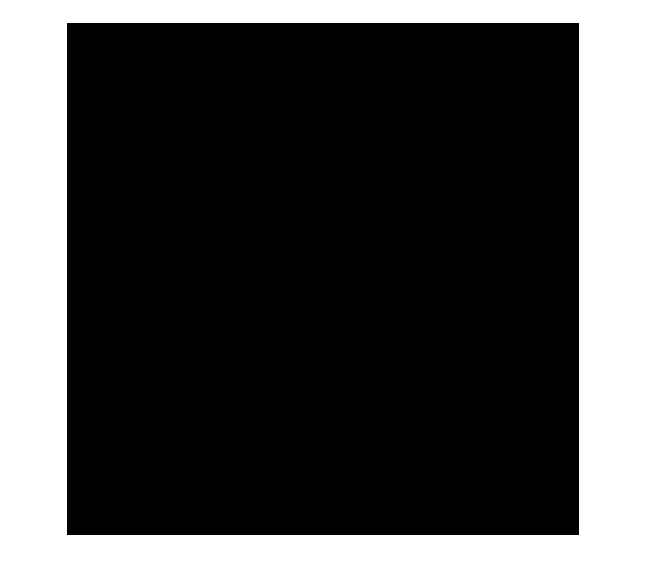


imshow(k/255);

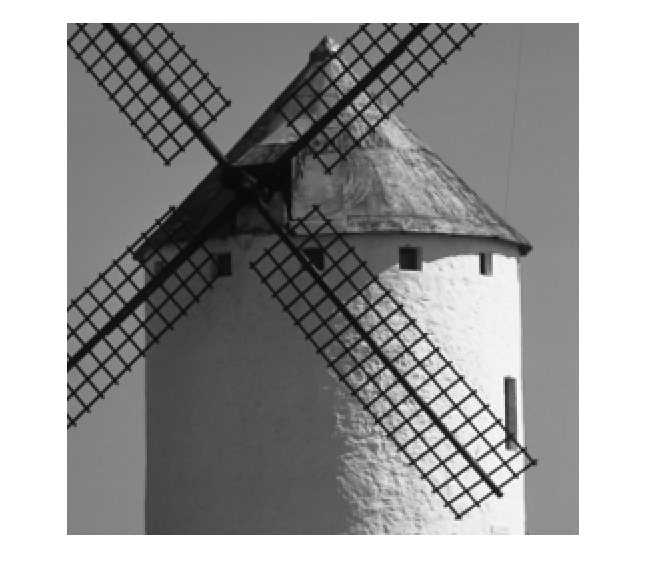

imshow(k2/255);

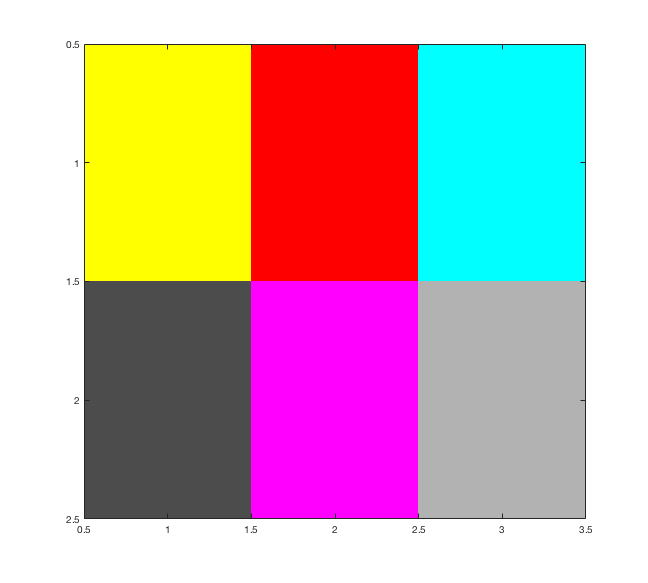



% (dvs. 2 rader och 3 kolumner).
% 1. Gult (Röd + Grön), upp till vänster
% 2. Röd, upp-mitten
% 3. Cyan (Grön + Blå), upp till höger
% 4. Mörkgrå, ner till vänster
% 5. Magenta (Röd + Blå), ner-mitten
% 6. Ljusgrå, ner till höger

map=([1 1 0; 1 0 0 ; 0 1 1; 0.3 0.3 0.3; 1 0 1; 0.7 0.7 0.7]);
image([1 , 2 , 3 ; 4, 5, 6,]);
colormap(map);

clear

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15];

N(1:3:end, 1);
N(1:3:end, :);

clear
v1=[1, 1, 1, 1];
v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1];
s1=sum(v1 .* v2);
% s2=sum(v1 .* v3);
clear

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


clear

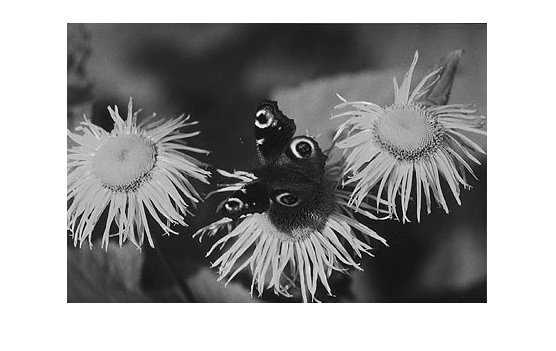


bild = imread('Butterfäly.tif');
bild = double(bild)/255;
bild = im2double(bild);
mygray = bild(:,:,2);
imshow(mygray);

imwrite(mygray, 'mygray.png')

b61= mygray(1:2:end, 1:2:end)

b61 =     0.3216    0.3216    0.3804    0.3686    0.3569    0.3412    0.3373    0.3294    0.3373    0.3765    0.4000    0.4275    0.4157    0.4000    0.4000    0.3922    0.3569    0.3961    0.3765    0.3843    0.3529    0.3608    0.3529    0.3569    0.3373    0.3333    0.3137    0.3020    0.3176    0.3059    0.3020    0.3020    0.2784    0.2824    0.2863    0.2902    0.2863    0.2784    0.2863    0.2784    0.2706    0.2627    0.2784    0.2824    0.2667    0.2745    0.2588    0.2863    0.2588    0.2824
    0.3569    0.3608    0.3725    0.3725    0.3451    0.3686    0.3373    0.3333    0.3529    0.3922    0.3961    0.4039    0.3961    0.3961    0.4078    0.3922    0.4039    0.3686    0.3804    0.3725    0.3804    0.3686    0.3608    0.3451    0.3373    0.3294    0.3216    0.3294    0.3176    0.3137    0.3098    0.3059    0.2980    0.2980    0.2980    0.2980    0.2902    0.2863    0.2784    0.2902    0.2784    0.2745    0.2784    0.2784    0.2784    0.2824    0.2706    0.2941    0.2980   

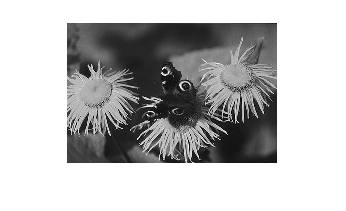


imshow(b61);

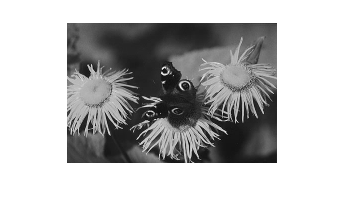

imwrite(b61, 'b61.png');

b62 = samplaner(mygray);
imshow(b62);

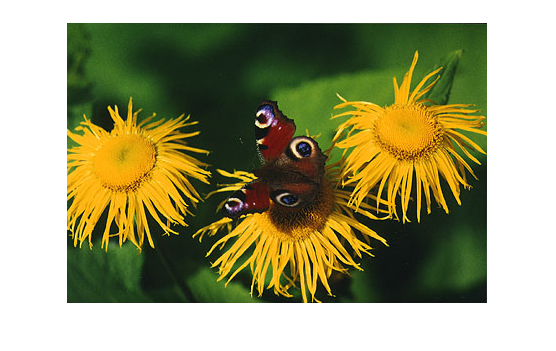

imwrite(b62,'b62.png');

b63_nearest = (imresize(b61,2,'nearest'));
b63_linear = (imresize(b61,2,'bilinear'));
b63_cubic = (imresize(b61,2,'bicubic'));

imwrite(b63_nearest, 'b63_nearest.png');
imwrite(b63_linear, 'b63_linear.png');
imwrite(b63_cubic,'b63_cubic.png');

mycolorimage = imread('Butterfly.tif');
imshow(mycolorimage)

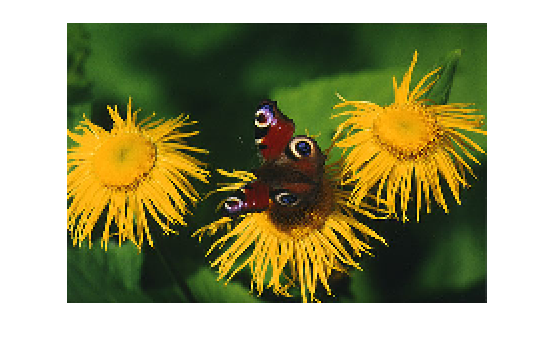

mycolorimage2 = double(mycolorimage)/255;
mycolorimage3 = im2double(mycolorimage);

b64 = imresize(mycolorimage3,0.5,'nearest');
b64 = imresize(b64,2,'nearest');
imshow(b64);

imwrite(b64,'b64.png');


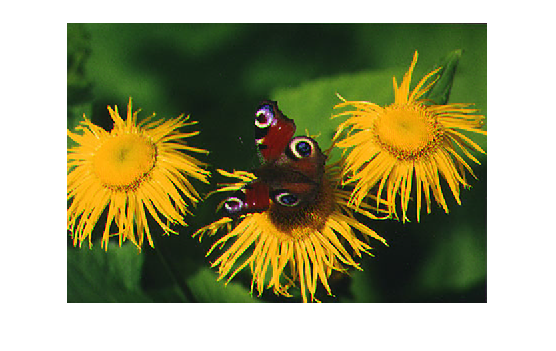

RR = mycolorimage(:, :, 1);
GG = mycolorimage(:, :, 2);
BB = mycolorimage(:, :, 3);
RR = imresize(RR,0.5,'nearest');
RR = imresize(RR,2,'nearest');
BB = imresize(BB,0.5,'nearest');
BB = imresize(BB,2,'nearest');
b65 = cat(3, RR, GG, BB);
imshow(b65);

imwrite(b65, 'b65.png')

mycolorimage = imread('Butterfly.tif');
R3 = imresize(mycolorimage(:, :, 1),0.5,'nearest');
R3 = imresize(R3,2,'nearest');
G3 = imresize(mycolorimage(:, :, 2),0.5,'nearest');
G3 = imresize(G3,2,'nearest');
BB = mycolorimage(:, :, 3);
b67 = cat(3, R3, G3, BB);
imshow(b67);
imwrite(b67,'b67.png');

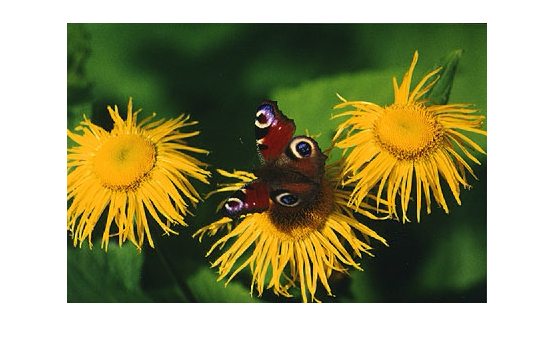

clear;
mycolorimage = imread('butterfly.tif');
mycolorimage = double(mycolorimage) / 255;

R = mycolorimage(:, :, 1);
G = mycolorimage(:, :, 2);
B = mycolorimage(:, :, 3);
bild1 = R+G+B;
bild2 = R-G;
bild3 = R+G-2*B;
bild2 = imresize(bild2,0.5,'nearest');
bild2 = imresize(bild2,2,'nearest');
bild3 = imresize(bild3,0.5,'nearest');
bild3 = imresize(bild3,2,'nearest');
R2 = bild1/3+bild2/2+bild3/6; 
G2 = bild1/3-bild2/2+bild3/6;
B2 = bild1/3-bild3/3;
b68 = cat(3,R2,G2,B2);
imshow(b68);

imwrite(b68,'b68.png');

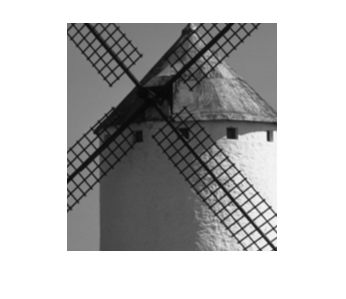

udda_bild = imread('kvarn_udda.tif');
udda_bild = double(udda_bild)/255;
udda_bild = im2double(udda_bild);
udda_bild2 = samplaner(udda_bild);
imshow(udda_bild2);